This script runs through the basics of an optimal control problem using dynamic programming. We will setup grids in the state and control spaces and then study the solution to the problem on the grid. This approach is VERY storage intensive, and will not work for systems with complex dynamics. I would limit such brute force to 4 states maximum.

System to Control

Let's solve a standard tracking problem, i.e. we have a mass and want to move it point-to point in a certain time.


$$\dot{x}_1 = x_2$$



$$\dot{x}_2 = u$$



$$|u|<1$$


Let me get these dynamics in discrete time using the backward difference approximation (to maintain the state meanings).

T = 0.1;  %Sampling time
A = [0 1;0 0];
B = [0;1];
C = [1 0];
Ad = [eye(2)+T*A];
Bd = T*B;
sys = ss(Ad,Bd,C,[],T)

sys =
 
  A = 
        x1   x2
   x1    1  0.1
   x2    0    1
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



Setup Discretized Space

X1 = [-2:0.5:2]';  %Possible positions -  I'm being generous!
X2 = [-2:0.25:2]';  %Again I'm being generous.  Better to think before this is established.
U = [-10:1:10]';  %Initialize the control vector
N = 10;  %How many time steps?  I will iterate on this.
J = 100000*ones(length(X1),length(X2),N);  %Setup an initial large cost matrix - if the numbers don't change, that indicates infeasibility
Ustar = 100000*ones(length(X1),length(X2),N-1);  %The optimal control - clearly these values will shrink!  Give N-1 controls in all.

Cost Function

Here my goal is to simply solve the final cost problem. Basically, I want the object to stop at x = 1. 

for jj = 1:length(X1)
        for kk = 1:length(X2) 
            J(jj,kk,end) = 1/2*100*(X1(jj)-1)^2+1/2*1000*(X2(kk))^2;  %Want zero velocity and position = 1 at the last step. 
        end
end

Backward Solution

for ii = 1:N-1
    for jj = 1:length(X1)
        for kk = 1:length(X2)
            for ll = 1:length(U)
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %Calculate the next state - here are the system dynamics.
                X0 = [X1(jj);X2(kk)];
                Xn = Ad*X0+Bd*U(ll);
                X1n = Xn(1);
                X2n = Xn(2);
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %Update the optimal costs / controls
                if (X1n <= X1(end) & X1n >= X1(1))
                    if (X2n <= X2(end) & X2n >= X2(1))
                        dJ = interpn(X1,X2,J(:,:,N-ii+1),X1n,X2n);%+1/2*X1(jj)^2+1/2*X2(kk)^2;  %Interpolate to find costs between grid points and add running cost
                        if dJ<J(jj,kk,N-ii)
                            J(jj,kk,N-ii) = dJ;
                            Ustar(jj,kk,N-ii) = U(ll);
                        end
                    end
                end
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            end
        end
    end
end

Forward Solution

Now we apply the optimal control and find the optimal trajectory given a starting point.

%Setup initial conditions
X1traj(1) =1.1;
X2traj(1) = 0;
%Find the optimal cost - is it feasible?
interpn(X1,X2,J(:,:,1),X1traj(1),X2traj(1))

ans = 0.6503

%Find initial optimal control
Uact(1) = interpn(X1,X2,Ustar(:,:,1),X1traj(1),X2traj(1));
%Roll dynamics forward, calculating optimal controls as we go
for ii = 2:N-1
     X0 = [X1traj(ii-1);X2traj(ii-1)];
     Xn = Ad*X0+Bd*Uact(ii-1);
     X1traj(ii) = Xn(1);
     X2traj(ii) = Xn(2);
     Uact(ii) = interpn(X1,X2,Ustar(:,:,ii),X1traj(ii),X2traj(ii));
end
%Find the final values of the trajectory based on the final control input
X0 = [X1traj(ii);X2traj(ii)];
Xn = Ad*X0+Bd*Uact(ii);
X1traj(ii+1) = Xn(1);
X2traj(ii+1) = Xn(2);

Let's test the solution.

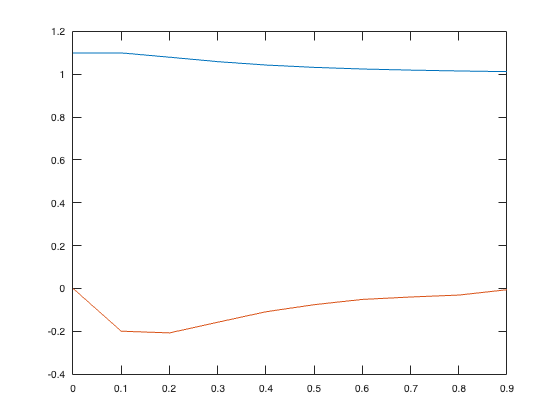

 plot([0:T:(N-1)*T],[X1traj;X2traj])